tbl=readtable('clean_yellow_sample_2016_06.csv');
summary(tbl)


Variables:

    pickup_longitude: 1029593×1 double
        Values:

            最小值    -115.17           
            中位数    -73.981           
            最大值    -56.643           

    pickup_latitude: 1029593×1 double
        Values:

            最小值    33.611           
            中位数    40.755           
            最大值    51.098           

    dropoff_longitude: 1029593×1 double
        Values:

            最小值    -115.18            
            中位数    -73.979            
            最大值     106.25            

    dropoff_latitude: 1029593×1 double
        Values:

            最小值    33.895            
            中位数    40.755            
            最大值    50.312            

    trip_distance: 1029593×1 double
        Values:

            最小值    0.01           
            中位数    1.72           
            最大值     500           

    passenger_count: 1029593×1 double
    

# **Please note! I select the following range and divide them into 100*100 (as well as 50*50) girds!**

latitude range [40.6,40.85]

longitude range [-74.05,-73.75]

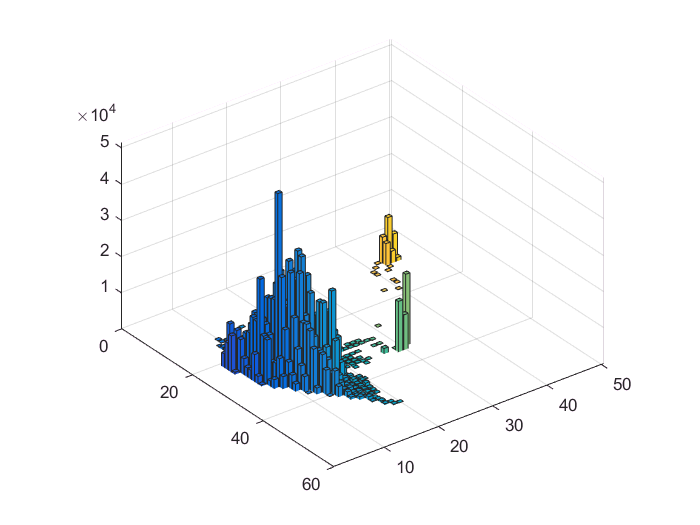


yedges=linspace(40.6,40.85,50);%latitude
xedges=linspace(-74.05,-73.75,50);%longitude
[tab,I,J]=hist3d(tbl.pickup_longitude,tbl.pickup_latitude,tbl.passenger_count,xedges,yedges);
C=tab;C(C<10)=NaN; %colormap
figure
colormap default
bar3(tab)
zlim([100 max(max(tab))])

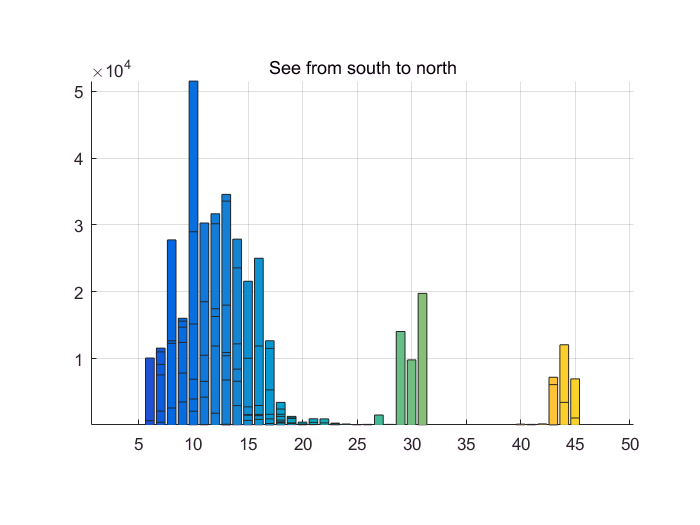

bar3(tab)
view([0 -1 0])
zlim([100 max(max(tab))])
title('See from south to north')

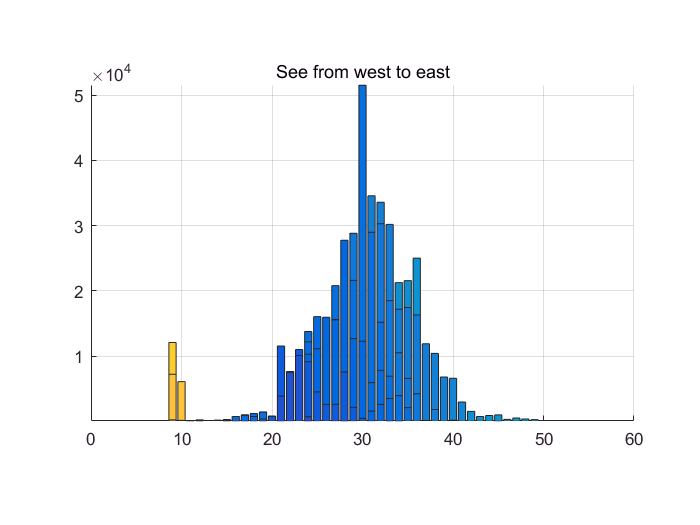


bar3(tab)
view([-1 0 0])
zlim([100 max(max(tab))])
title('See from west to east')

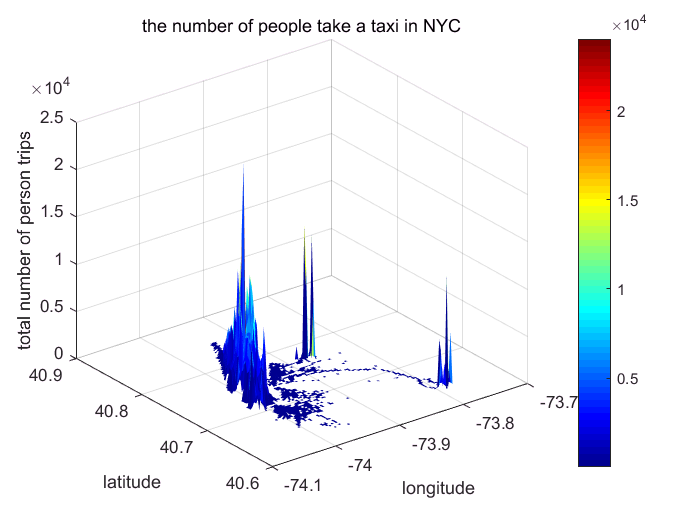

yedges=linspace(40.6,40.85,100);%latitude
xedges=linspace(-74.05,-73.75,100);%longitude
[tab,I,J]=hist3d(tbl.pickup_longitude,tbl.pickup_latitude,tbl.passenger_count,xedges,yedges);
C=tab;C(C<10)=NaN; %colormap
figure
surf(xedges,yedges,tab,C,'linestyle','none')
colorbar
colormap jet
xlabel('longitude')
ylabel('latitude')
zlabel('total number of person trips')
title('the number of people take a taxi in NYC')

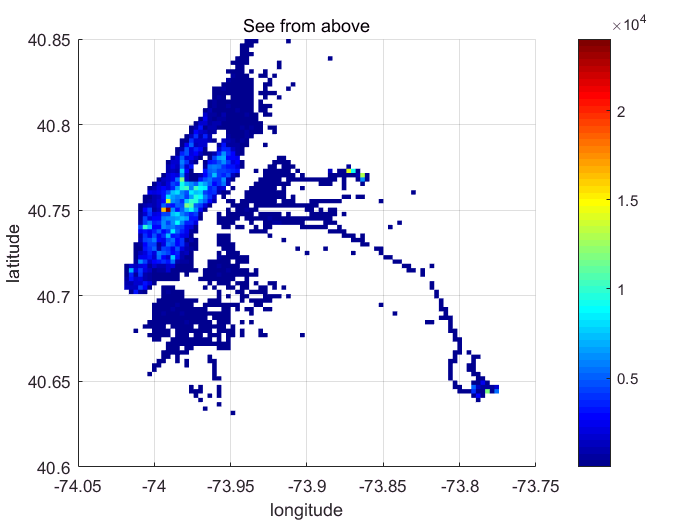

surf(xedges,yedges,tab,C,'linestyle','none')
colormap jet
colorbar
xlabel('longitude')
ylabel('latitude')
zlabel('total number of person trips')
title('See from above')
view(2)

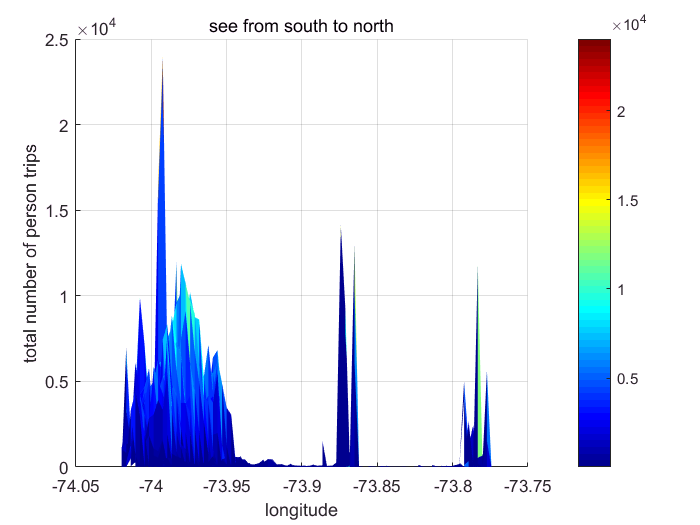


surf(xedges,yedges,tab,C,'linestyle','none')
colorbar
view([0 -1 0])
title('see from south to north')
xlabel('longitude')
ylabel('latitude')
zlabel('total number of person trips')

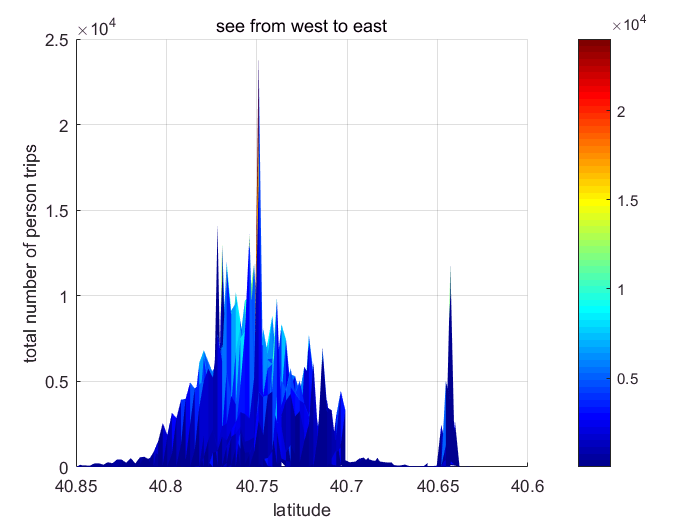


surf(xedges,yedges,tab,C,'linestyle','none')
colorbar
view([-1 0 0])
title('see from west to east')
xlabel('longitude')
ylabel('latitude')
zlabel('total number of person trips')

## Now we take a look at the place where most (most means above median) of the trips originate. We find the busiest place in NYC!

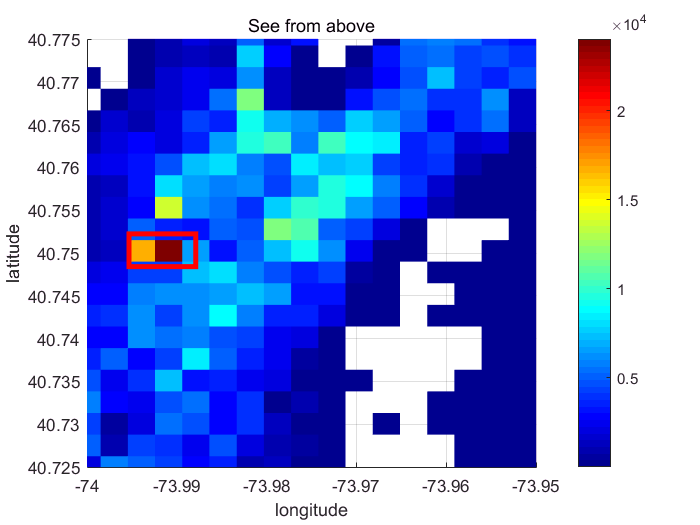

yedges=linspace(40.6,40.85,100);%latitude
xedges=linspace(-74.05,-73.75,100);%longitude
[tab,I,J]=hist3d(tbl.pickup_longitude,tbl.pickup_latitude,tbl.passenger_count,xedges,yedges);
tab(tab<median(tab(:)))=NaN;
C=tab;C(C==0)=NaN; %colormap
surf(xedges,yedges,tab,C,'linestyle','none')
colormap jet
colorbar
xlabel('longitude')
ylabel('latitude')
zlabel('total number of person trips')
title('See from above')
view(2)
xlim([-74,-73.95])
ylim([40.725,40.775])
annotation('rectangle',...
    [0.184375 0.492227979274611 0.0953125 0.0621761658031088],'Color',[1 0 0],...
    'LineWidth',3);

## The busiest are is -74<lat<-73.99 and 40.7485<lon<40.7495

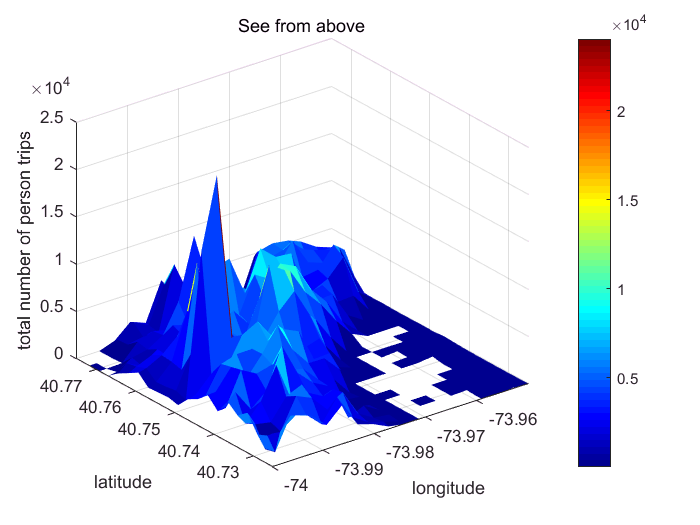

figure
surf(xedges,yedges,tab,C,'linestyle','none')
colormap jet
colorbar
xlabel('longitude')
ylabel('latitude')
zlabel('total number of person trips')
title('See from above')
xlim([-74,-73.95])
ylim([40.725,40.775])